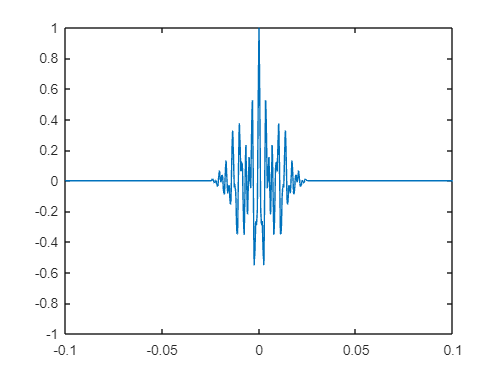

f = 293.5780

clear

clc

fs = 8000;
load("testwave294.mat");
[autocor,lags] = xcorr(ndat(1:200),fs,'coeff');
plot(lags/fs,autocor)
axis([-0.1 0.1 -1 1])
[pklg,lclg] = findpeaks(autocor,'MinPeakheight',0.3*max(autocor));
f=fs/mean(diff(lclg))